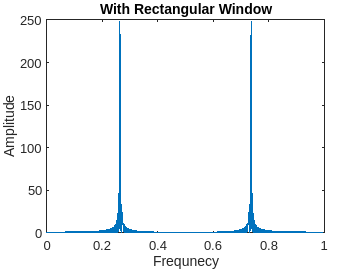

alpha = 1 + mod(280, 3); 
% 1
% duration = 2; % Duration in seconds
% sampling_rate = 120; % Sampling rate in samples/second
% frequency = 15 * alpha; % Frequency of the signal in Hz
% num_samples = sampling_rate * duration;
% time = linspace(0, duration, num_samples);
% signal = sin(2 * pi * frequency * time);
% 
% % Compute the DFT of the first 120 samples
% N1 = 120;
% dft1 = fft(signal(1:N1));
% 
% % Compute the frequency axis for the DFT
% frequencies1 = (0:N1-1) * (sampling_rate / N1);
% 
% % Compute the DFT of the first 130 samples
% N2 = 130;
% dft2 = fft(signal(1:N2));
% 
% % Compute the frequency axis for the DFT
% frequencies2 = (0:N2-1) * (sampling_rate / N2);
% 
% % Plot the magnitude of the DFT for the first 120 and 130 samples
% figure;
% subplot(2, 1, 1);
% stem(frequencies1, abs(dft1));
% xlabel('Frequency (Hz)');
% ylabel('Magnitude');
% title('DFT of the first 120 samples');
% 
% subplot(2, 1, 2);
% stem(frequencies2, abs(dft2));
% xlabel('Frequency (Hz)');
% ylabel('Magnitude');
% title('DFT of the first 130 samples');

% 2
% Parameters
% A_values = 140;
% B_values = 146;
% fs = 200; % Sampling rate (samples per second)
% duration = 10; % Duration of the signal (seconds)
% 
% % Time vector
% t = 0:1/fs:duration;
% 
% % Generate the signal xa(t)
% xa = 0.1 * sin(A * pi * t) + cos(B * pi * t);
% 
% % Calculate the DFT for different sample sizes
% sample_sizes = [215, 415, 1115, 1515, 1915];
% 
% for j = 1:length(sample_sizes)
%    N = sample_sizes(j)
%    X = fft(xa(1:N), N); % Compute the DFT
% 
%    % Plot the DFT
%    figure;
%    stem(abs(X));
%    title(['DFT of xa(t) for N = ' num2str(N)]);
%    xlabel('Frequency Bin');
%    ylabel('Magnitude');
% end

% 3
% duration = 10;             % Duration in seconds
% sampling_rate = 200;       % Sampling rate in samples/second
% 
% A = 140; % A values
% B = 146; % B values
% 
% % Time vector
% t = 0:1/sampling_rate:duration;
% 
% % Generate signal xa(t)
% xa = 0.1 * sin(A * pi * t) + cos(B * pi * t);
% 
% % Sample the signal
% sample_indices = [215, 415, 1115, 1515, 1915];
% for sample_idx = 1:length(sample_indices)
%     num_samples = sample_indices(sample_idx);
%     sampled_xa = xa(1:num_samples);
% 
%     window = hann(num_samples);
% 
%     windowed_xa = sampled_xa .* window';
% 
%     % Compute the DFT
%     X = fft(windowed_xa);
% 
%     % Plot the DFT
%     figure;
%     plot(abs(X));
%     title(['DFT of windowed xa(t) for \alpha = ', num2str(alpha), ', A = ', num2str(A), ', B = ', num2str(B), ', ', num2str(num_samples), ' samples']);
%     xlabel('Frequency Bin');
%     ylabel('Magnitude');
%     xlim([0, num_samples]);
% end


% 4
load("/MATLAB Drive/manish/Exp4Data2.txt")
x = Exp4Data2 ;
m = abs(fft(x,10000));
f = (0:length(m)-1)*1/length(m);
figure(1)
plot(f,m)
title("With Rectangular Window")
xlabel("Frequnecy");
ylabel("Amplitude");

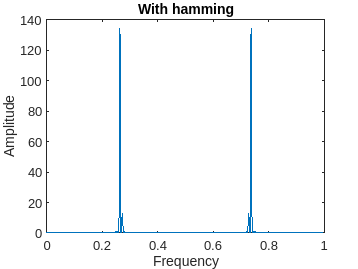


w = hamming(500);
x1 = Exp4Data2.* w' ;
m1 = abs(fft(x1,10000));
f1 = (0:length(m1)-1)*1/length(m1);
figure(2)
plot(f1,m1)
title("With hamming")
xlabel("Frequency");
ylabel("Amplitude");